clear all
close all
clc

rng('default');

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',5);

% plot(inz)
% 
% FY = mag2db(abs(fft(inz)));
% 
% figure;
% hold on
% plot(FY(1:floor(end/2)))
% hold off



% Choose parameters
% rng(2)
n=2; m=2;
mn = n+m;

inlags=[1 2 3 4];
outlags =[0 1 2 3 4];

d=numel(inlags)+numel(outlags)-1;

maxranksynth =5;
rk = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxranksynth));

scale = 9;
synth = 0.5+ scale*(double(rand(mn*ones(1,d))>0.5)-0.5);

TN = trunttsvd(synth,rk)

TN = struct with fields:
    core: {[1×4×4 double]  [4×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×4 double]  [4×4 double]}
      sz: [8×3 double]



norm(TN.core{end})

ans = 137.1025

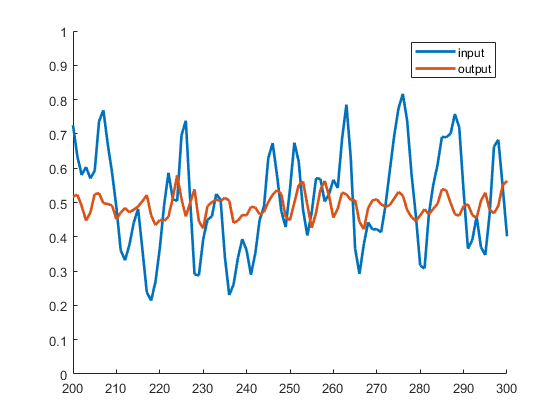


% siminput(1:21)=heaviside(-10:10)/2;
siminput = inz;
simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth', 2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([200 300 0 1])
legend('input','output')

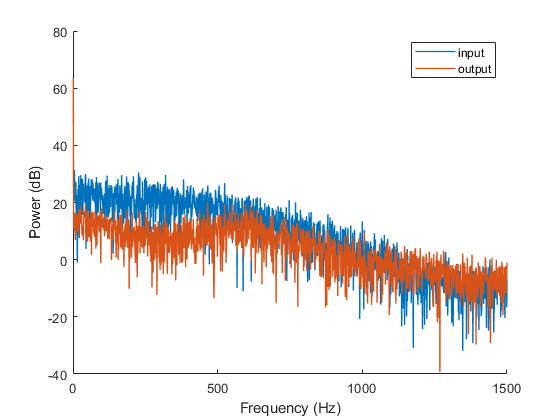


FX = mag2db(abs(fft(siminput)));
FY = mag2db(abs(fft(simoutput)));
figure;
hold on
plot(FX(1:floor(end/2)),'Linewidth',1)
plot(FY(1:floor(end/2)),'Linewidth',1)
hold off
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend('input','output')

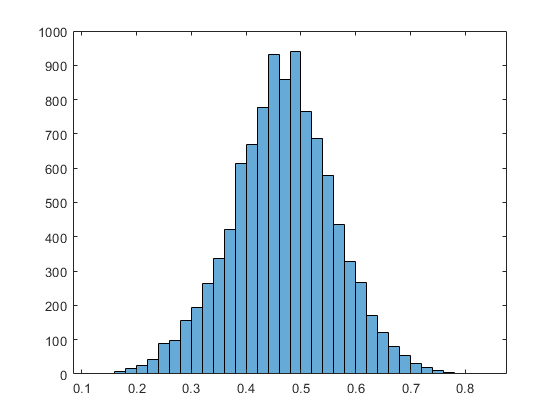


testfeatures = rand(10000,8);
testput = evalspline(TN,testfeatures,n,m);

% plot(testput)
histogram(testput')

% axis([000 200 0 1])



input = siminput(10:2000);
output = simoutput(10:2000);
tinput = siminput(2001:end);
toutput = simoutput(2001:end);


Preprocessing Data

tic

% Choose the lags for the input
inlags=[1 2 3 4];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-(1900):end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-(900):end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2 3 4];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-(1900):end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-(900):end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                  %degree B-spline
m = 2;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);



Initialize tensor train -----------------------------------------------------------------

% Choose TT-ranks
maxrank =5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));


LAMBDA = 10.^[-12:1:9]

LAMBDA = 	1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000



LAMBDA = 10.^(-8)

LAMBDA = 1.0000e-08

for period = 1:numel(LAMBDA)

    for trial = 1:5
[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio



Compression: 0.0090332


Compression: 0.0090332


Compression: 0.0090332


Compression: 0.0090332


Compression: 0.0090332


Optimize TT cores

lambda= LAMBDA(period);

difforder=2;
MAXITR = 4*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);

% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)

% plot(rez)

Evaluate Test data

 
yhat = evalspline(TN,tfeaturez,n,m);
% erboi = (yhat-yt);
% histogram((erboi)');
% VAF = 1-var(erboi)/var(yt)
% MSE = immse(yhat,yt)

RMSE_P(period,trial) = sqrt(immse(yhat,yt));

% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 200 -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


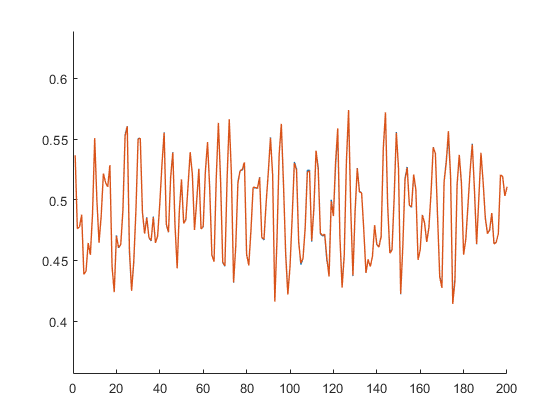

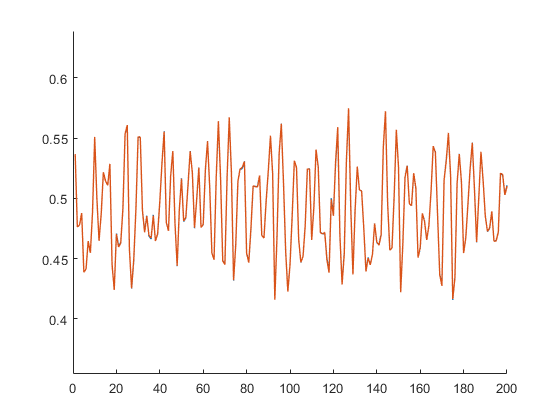

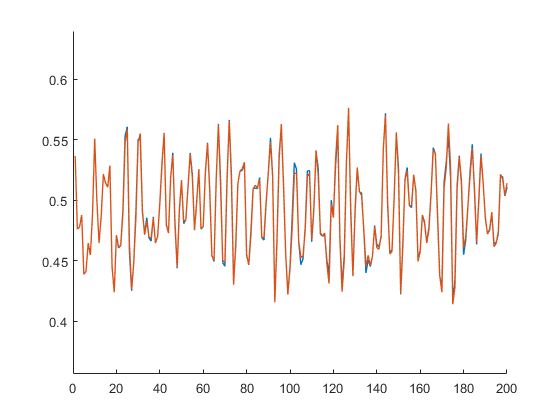

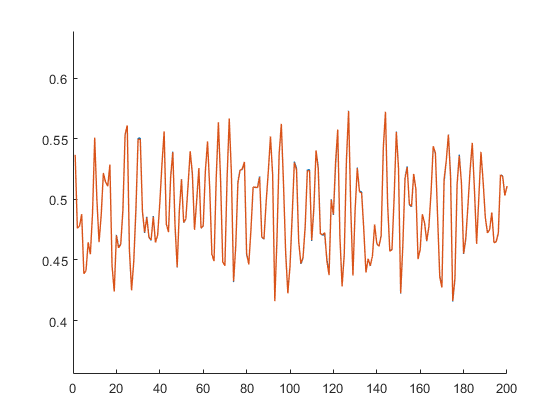

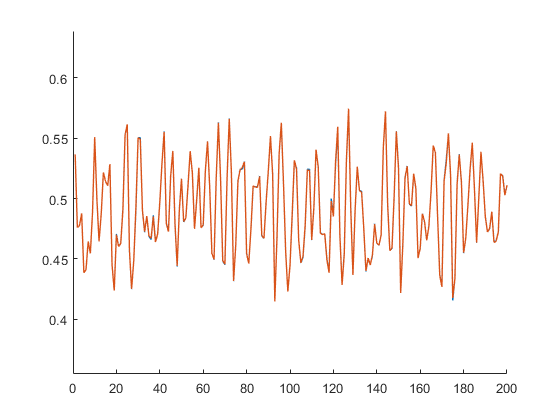

% plot(tinput)
% plot(toutput)

siminputz = tinput;
simoutputz = toutput(1:20);
numz = numel(outlags);
for j = 20:1000
simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutputz(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(toutput,'Linewidth',1)
plot(simoutputz,'Linewidth',1)
hold off
axis([0 200 -inf inf])


RMSE_S(period,trial) = sqrt(immse(toutput,simoutputz));
% MAPE(period) = mean(abs(toutput-simoutputz)./abs(toutput))
% RMSRE(period) = sqrt(sum((toutput-simoutputz).^2)/sum(toutput.^2))
% RRMSE(period) = sqrt((immse(toutput,simoutputz))/sum(toutput.^2))
% VAF(period) = 1-var(toutput-simoutputz)/var(toutput)
% RLOG(period) = mean(log(simoutputz./toutput))

toc

Elapsed time is 1.328778 seconds.


Elapsed time is 1.169620 seconds.


Elapsed time is 1.115913 seconds.


Elapsed time is 0.984145 seconds.


Elapsed time is 1.128594 seconds.


    end
end

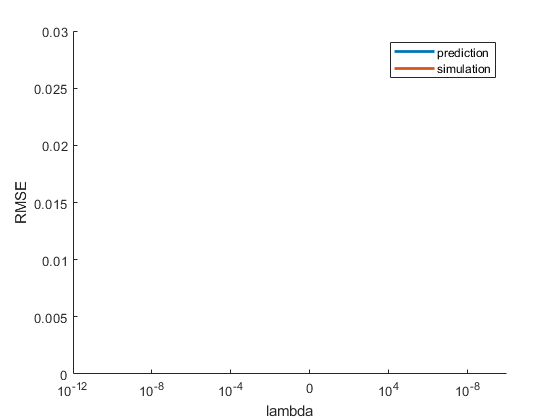

figure;
hold on
plot(log10(LAMBDA),mean(RMSE_P,2),'Linewidth',2)
plot(log10(LAMBDA),mean(RMSE_S,2),'Linewidth',2)
hold off
axis([-12 10 0 0.03])
xlabel('lambda')
ylabel('RMSE')
xticks([-12 -8 -4 0 4 8])
xticklabels({'10^{-12}','10^{-8}','10^{-4}','0','10^{4}','10^{-8}'})
legend('prediction','simulation')

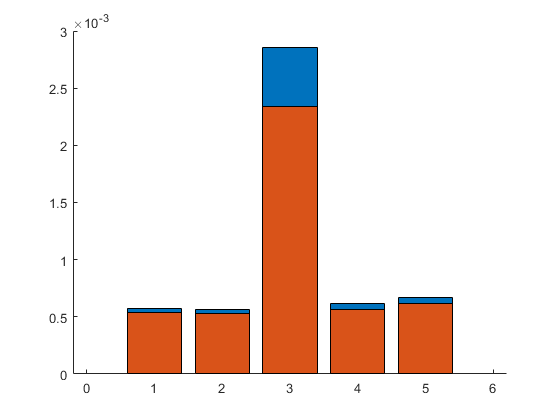

figure 
hold on
bar(RMSE_S)
bar(RMSE_P)
hold off

mean(RMSE_P)

ans = 9.1683e-04

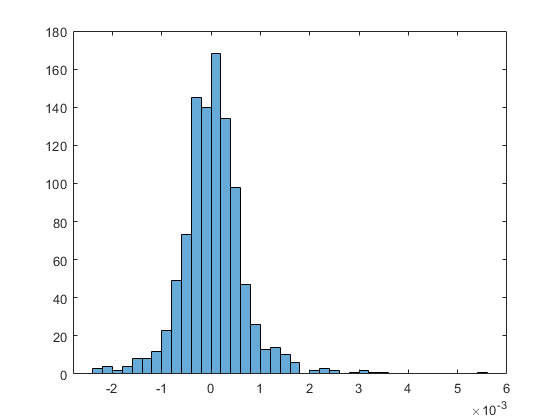


histogram(toutput-simoutputz)

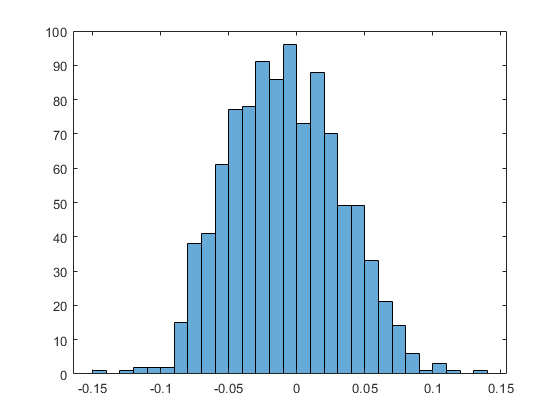


histogram(toutput-0.5)

sqrt(immse(toutput,0.5*ones(1000,1)))

ans = 0.0414